# Pretrained EfficientDet-D0 Network를 이용한 전이학습

The following code demonstrates how to perform transfer learning using the pretrained YOLO v4 network for object detection. This script uses the "configureYOLOv4" function to create a custom YOLO v4 network using the pretrained model.

## Setup

Add path to the source directory.

addpath('src');

## Download Pretrained Network

**YOLOv4-coco** **YOLOv4-tiny-coco** 

modelName = 'YOLOv4-tiny-coco';
model = helper.downloadPretrainedYOLOv4(modelName);

Pretrained YOLOv4-tiny-coco network already exists.



net = model.net;

## Load Data

해당 코드에서는 DeepFashion2 데이터셋 중 validation의 이미지와 annos 데이터를 가져옵니다. Python에서와 달리 matlab에서는 table 형태로 이미지의 위치와 annos 정보가 저장된 파일을 기반으로 데이터를 가져오기 때문에 데이터셋을 기반으로 .mat 파일을 생성해야 합니다. (별도 코드 참조)

%데이터셋
load petGT.mat

petGT.imageFilename = fullfile(pwd,'petImages',petGT.imageFilename)

petGT = 432×6 table
                                                                   imageFilename                                                                         Ginny                 Lucy                Madeline                 Kima                  Susan      
    ___________________________________________________________________________________________________________________________________________    _________________    __________________    ___________________    ___________________    _________________

    {'C:\Users\yoons\Sangjun\대학교\2022상반기-7학기\Capstone\pretrained-yolo-v4-main\pretrained-yolo-v4-main\petImages\Madeline\Madeline135.jpg'}    {0×0 double     }    {0×0 double      }    {[ 163 156 110 92]}    {0×0 double       }    {0×0 double     }
    {'C:\Users\yoons\Sangjun\대학교\2022상반기-7학기\Capstone\pretrained-yolo-v4-main\pretrained-yolo-v4-main\petImages\Lucy\Lucy120.jpg'        }    {0×0 double     }    {[65 304 143 145]}    {0×0 double       }    {0×0 double   

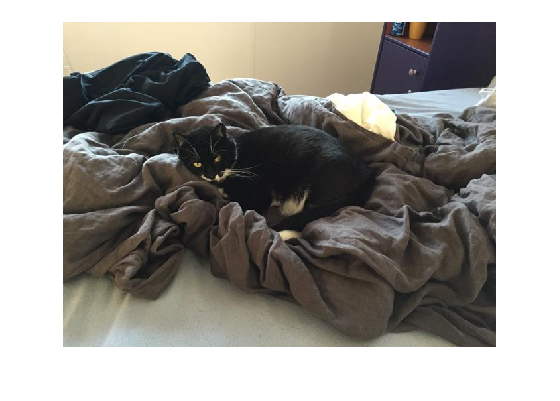

%이미지 보기
image1= imread(petGT.imageFilename{1});
imshow(image1)

%바운딩 박스 정보가 없는 인덱스 구하기
h=height(petGT);
idx=true(h,1);
for k = 1:h
    tmp=petGT(k,2:end);
    tmp=table2array(tmp);
    check=true(1);
    for j = 1:length(tmp)
        check = check & isempty((tmp{1,j}));
    end
    idx(k,1)=check;
end

%선별
idx

idx = 432×1 logical 배열
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


fpetGT=petGT(~idx,:)

fpetGT = 368×6 table
                                                                   imageFilename                                                                         Ginny                 Lucy                Madeline                 Kima                  Susan      
    ___________________________________________________________________________________________________________________________________________    _________________    __________________    ___________________    ___________________    _________________

    {'C:\Users\yoons\Sangjun\대학교\2022상반기-7학기\Capstone\pretrained-yolo-v4-main\pretrained-yolo-v4-main\petImages\Madeline\Madeline135.jpg'}    {0×0 double     }    {0×0 double      }    {[ 163 156 110 92]}    {0×0 double       }    {0×0 double     }
    {'C:\Users\yoons\Sangjun\대학교\2022상반기-7학기\Capstone\pretrained-yolo-v4-main\pretrained-yolo-v4-main\petImages\Lucy\Lucy120.jpg'        }    {0×0 double     }    {[65 304 143 145]}    {0×0 double       }    {0×0 double  

%데이터셋 구축
imDS = imageDatastore(fpetGT.imageFilename);
boxDS = boxLabelDatastore(fpetGT(:,2:end));
trainingData = combine(imDS,boxDS);

% % Use validateInputData to detect invalid images, bounding boxes or labels
% % i.e.,
% %
% % * Samples with invalid image format or containing NaNs
% % * Bounding boxes containing zeros/NaNs/Infs/empty
% % * Missing/non-categorical labels.
% %
% % The values of the bounding boxes should be finite, positive, non-fractional,
% % non-NaN and should be within the image boundary with a positive height and width.
% % Any invalid samples must either be discarded or fixed for proper training.

%데이터셋 유효검사, 바운딩 박스 정보 비어있는 이미지 포함시 오류 발생
% helper.validateInputData(trainingData);
% helper.validateInputData(testData);


## Data Augmentation

Data augmenation의 경우 원본 데이터를 학습과정에서 랜덤하게 변형시키는 것을 통해 학습 모델의 정확도를 향상시키는 방법입니다. Data augmentation 사용을 통해 training 데이터셋의 샘플 수를 늘리지 않아도 학습 데이터의 다양성을 추가할 수 있습니다.

'transform'이라는 함수의 사용을 통해 학습 데이터에서 커스텀 data augmentation을 적용할 수 있습니다. 'helper.augmentData' 함수를 통해 아래와 같은 augmentation들을 입력 데이터에 적용할 수 있습니다.

- Color jitter augmentation in HSV space

- Random horizontal flip

- Random scaling by 10 percent

augmentedTrainingData = transform(trainingData, @helper.augmentData);

% Read the same image four times and display the augmented training data.

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1,1}, 'Rectangle', data{1,2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData, 'BorderSize', 10)

% net

## Preprocess Training Data

위에서 진행된 augmented 학습 데이터를 학습 과정에 맞도록 preprocess하는 부분입니다.  'helper.preprocessTrainData 함수를 통해 입력 데이터를 모델에 적합하도록 아래의 과정을 거치는 preprocessing을 하게 됩니다.

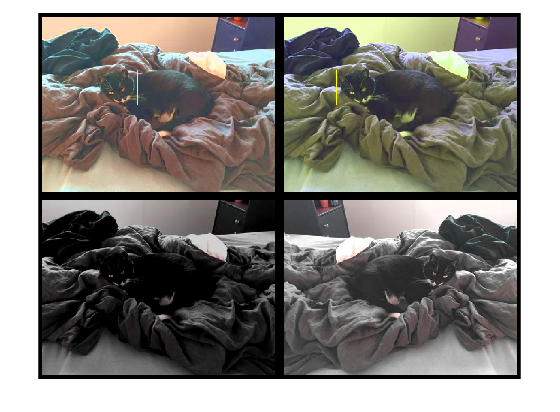

networkInputSize = net.Layers(1).InputSize;


% Preprocess the augmented training data to prepare for training. The preprocessData
% helper function, listed at the end of the example, applies the following preprocessing
% operations to the input data.
%
% * Resize the images to the network input size
% * Scale the image pixels in the range |[0 1]|.
preprocessedTrainingData = transform(augmentedTrainingData, @(data)helper.preprocessData(data, networkInputSize));

% Read the preprocessed training data.
data = read(preprocessedTrainingData);

% Display the image with the bounding boxes.
I = data{1,1};
bbox = data{1,2};
annotatedImage = insertShape(I, 'Rectangle', bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

% Reset the datastore.
reset(preprocessedTrainingData);

## Modify Pretrained YOLO v4 Network

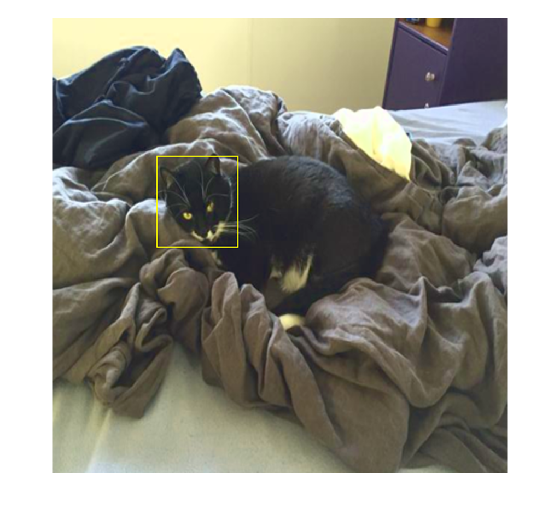

rng(0)
trainingDataForEstimation = transform(trainingData, @(data)helper.preprocessData(data, networkInputSize));
numAnchors = 6;
[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors);


% Specify the classNames to be used in the training.
%classNames = {'SST', 'LST', 'SSO', 'LSO', 'vest', 'sling', 'shorts', 'trousers', 'skirt', 'SSD', 'LSD', 'vestDress', 'slingDress'};
classNames = {'Ginny','Lucy','Madeline','Kima','Susan'};

% Configure the pretrained model for transfer learning using configureYOLOv4
% function. This function will return the modified layergraph, networkoutput
% names, reordered anchorBoxes and anchorBoxMasks to select anchor boxes to
% use in the detection heads.
[lgraph, networkOutputs, anchorBoxes, anchorBoxMasks] = configureYOLOv4(net, classNames, anchorBoxes, modelName);

## Specify Training Options

트레이닝 옵션을 각각의 필요에 따라서 수정하면 됩니다.

numEpochs = 5;
miniBatchSize = 4;
learningRate = 0.001;
warmupPeriod = 1000;
l2Regularization = 0.001;
penaltyThreshold = 0.5;
velocity = [];

## Train Model

해당 코드에서는 매트랩에서 제공하는 Parallel Computing Toolbox를 통해 CUDA 사용이 가능한 로컬 NVDIA GPU를 통해 학습합니다.

'minibatchqueue' 함수를 통해 전처리된 학습 데이터를 batch 크기에 맞게 분리하게 됩니다. 이때, 'createBatchData' 함수를 같이 사용해서 batch로 분리된 이미지들, 해당하는 bounding box들과 레이블을 받게 됩니다. Batch 과정을 더 빠르게 진행하고 싶다면 'dispatchBackground'가 true로 설정되어야 병렬풀의 사용이 보장됩니다. 

Use the minibatchqueue function to split the preprocessed training data into batches with the supporting function createBatchData which returns the batched images and bounding boxes combined with the respective class IDs. For faster extraction of the batch data for training, dispatchInBackground should be set to "true" which ensures the usage of parallel pool.

% 전이학습 부분, 스킵 후 다음섹션에서 학습된 네트워크 로드가능, 참고로 줄 주석 단축키 CTRL + R, 지우기는 ctrl + t 

if canUseParallelPool
    dispatchInBackground = true;
else
    dispatchInBackground = false;
end

mbqTrain = minibatchqueue(preprocessedTrainingData, 2,...
    "MiniBatchSize", miniBatchSize,...
    "MiniBatchFcn", @(images, boxes, labels) helper.createBatchData(images, boxes, labels, classNames), ...
    "MiniBatchFormat", ["SSCB", ""],...
    "DispatchInBackground", dispatchInBackground,...
    "OutputCast", ["", "double"]);

% To train the network with a custom training loop and enable automatic differentiation,
% convert the layer graph to a dlnetwork object. Then create the training progress
% plotter using supporting function configureTrainingProgressPlotter.
%
% Finally, specify the custom training loop. For each iteration:
%
% * Read data from the minibatchqueue. If it doesn't have any more data, reset
% the minibatchqueue and shuffle.
% * Evaluate the model gradients using dlfeval and the modelGradients function.
% The function modelGradients, listed as a supporting function, returns the
% gradients of the loss with respect to the learnable parameters in net, the
% corresponding mini-batch loss, and the state of the current batch.
% * Apply a weight decay factor to the gradients to regularization for more
% robust training.
% * Determine the learning rate based on the iterations using the
% piecewiseLearningRateWithWarmup supporting function.
% * Update the network parameters using the sgdmupdate function.
% * Update the state parameters of net with the moving average.
% * Display the learning rate, total loss, and the individual losses (box loss,
% object loss and class loss) for every iteration. These can be used to interpret
% how the respective losses are changing in each iteration. For example, a sudden
% spike in the box loss after few iterations implies that there are Inf or NaNs
% in the predictions.
% * Update the training progress plot.

% The training can also be terminated if the loss has saturated for few epochs.

% Convert layer graph to dlnetwork.
net = dlnetwork(lgraph);

% Create subplots for the learning rate and mini-batch loss.
fig = figure;
[lossPlotter, learningRatePlotter] = helper.configureTrainingProgressPlotter(fig);

iteration = 0;

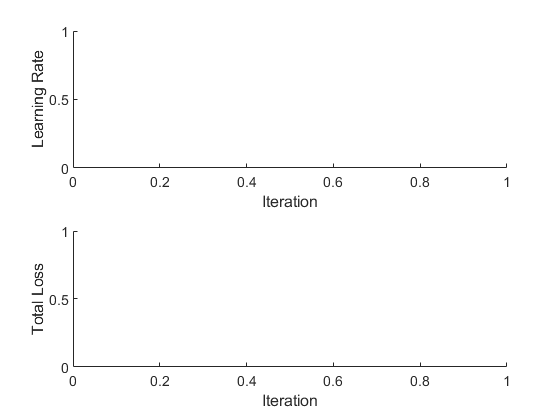

% Custom training loop.
for epoch = 1:numEpochs
    
    reset(mbqTrain);
    shuffle(mbqTrain);
    

    while(hasdata(mbqTrain))
        iteration = iteration + 1;
        
        [XTrain, YTrain] = next(mbqTrain);
        
        % Evaluate the model gradients and loss using dlfeval and the
        % modelGradients function.
        [gradients, state, lossInfo] = dlfeval(@modelGradients, net, XTrain, YTrain, anchorBoxes, anchorBoxMasks, penaltyThreshold, networkOutputs);
        
        % Apply L2 regularization.
        gradients = dlupdate(@(g,w) g + l2Regularization*w, gradients, net.Learnables);
        
        % Determine the current learning rate value.
        currentLR = helper.piecewiseLearningRateWithWarmup(iteration, epoch, learningRate, warmupPeriod, numEpochs);
        
        % Update the network learnable parameters using the SGDM optimizer.
        [net, velocity] = sgdmupdate(net, gradients, velocity, currentLR);
        
        % Update the state parameters of dlnetwork.
        net.State = state;
        
        % Display progress.
        if mod(iteration,10)==1
            helper.displayLossInfo(epoch, iteration, currentLR, lossInfo);
        end
        
        % Update training plot with new points.
        helper.updatePlots(lossPlotter, learningRatePlotter, iteration, currentLR, lossInfo.totalLoss);
    end
end

% Save the trained model with the anchors.
anchors.anchorBoxes = anchorBoxes;
anchors.anchorBoxMasks = anchorBoxMasks;

% 모델 저장

Epoch : 1 | Iteration : 1 | Learning Rate : 1e-15 | Total Loss : 2640.0066 | Box Loss : 2.8507 | Object Loss : 2632.8542 | Class Loss : 4.3018
Epoch : 1 | Iteration : 11 | Learning Rate : 1.4641e-11 | Total Loss : 2629.0159 | Box Loss : 11.1593 | Object Loss : 2613.4795 | Class Loss : 4.3772
Epoch : 1 | Iteration : 21 | Learning Rate : 1.9448e-10 | Total Loss : 2607.2825 | Box Loss : 2.6831 | Object Loss : 2598.6997 | Class Loss : 5.8996


% save('yolov4_trained', 'net', 'anchors');
% 학습된 모델 불러오기
load yolov4_trained.mat

## Evaluate Model

Computer Vision System Toolbox에서는 객체 인식 평가 함수들을 제공합니다. 이를 통해 average precision 과 로그 평균 오차율에 대해 측정할 수 있습니다. 여기서는 average precision을 사용하여 평가합니다. 

%테스트 데이터셋으로 평가

confidenceThreshold = 0.5;
overlapThreshold = 0.5;

% Create a table to hold the bounding boxes, scores, and labels returned by
% the detector.
numImages = size(testDataTbl, 1);
results = table('Size', [0 3], ...
    'VariableTypes', {'cell','cell','cell'}, ...
    'VariableNames', {'Boxes','Scores','Labels'});

% Run detector on images in the test set and collect results.
reset(testData)
while hasdata(testData)
    % Read the datastore and get the image.
    data = read(testData);
    image = data{1};
    
    % Run the detector.
    executionEnvironment = 'auto';
    [bboxes, scores, labels] = detectYOLOv4(net, image, anchors, classNames, executionEnvironment);
    
    % Collect the results.
    tbl = table({bboxes}, {scores}, {labels}, 'VariableNames', {'Boxes','Scores','Labels'});
    results = [results; tbl];
end

% Evaluate the object detector using Average Precision metric.
[ap, recall, precision] = evaluateDetectionPrecision(results, testData);

% The precision-recall (PR) curve shows how precise a detector is at varying
% levels of recall. Ideally, the precision is 1 at all recall levels.

% Plot precision-recall curve.
figure
plot(recall, precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', ap))

## Detect Objects Using Trained YOLO v4

학습된 네트워크를 통해 아래의 과정을 거쳐 객체인식을 하게 됩니다.

- Read an image.

- Convert the image to a dlarray and use a GPU if one is available..

- Use the supporting function detectYOLOv4 to get the predicted bounding boxes, confidence scores, and class labels.

- Display the image with bounding boxes and confidence scores.

%테스트 이미지 데이터셋 미리 만든 경우 사용
% % Read the datastore.
% reset(testData)
% data = read(testData);
% 
% % Get the image.
% I = data{1};
% 
% % Run the detector.
% executionEnvironment = 'auto';
% [bboxes, scores, labels] = detectYOLOv4(net, I, anchors, classNames, executionEnvironment);
% 
% % Display the detections on image.
% if ~isempty(scores)
%     I = insertObjectAnnotation(I, 'rectangle', bboxes, scores);
% end
% figure
% imshow(I)

%테스트 이미지 불러오기
timg=imread('testImages\Ginny.jpg');
figure
imshow(timg)

%이미지 분류matlab:matlab.internal.language.introspective.errorDocCallback('gpuArray/reshape')
%classNames = {'SST', 'LST', 'SSO', 'LSO', 'vest', 'sling', 'shorts', 'trousers', 'skirt', 'SSD', 'LSD', 'vestDress', 'slingDress'};
classNames = {'Ginny','Lucy','Madeline','Kima','Susan'};

executionEnvironment = 'auto';
[bboxes, scores, labels] = detectYOLOv4(net, timg, anchors, classNames, executionEnvironment);
if ~isempty(scores)
    I = insertObjectAnnotation(timg, 'rectangle', bboxes, labels);
end
figure
imshow(I)

%확률 추가
labelScore = cell(size(labels));
for k = 1:length(labels)
    labelScore{k} = [char(labels(k)),':',num2str(scores(k))];
end
executionEnvironment = 'auto';
detect = insertObjectAnnotation(timg,"rectangle",bboxes,labelScore);
figure
imshow(detect)

%clc
%clear
%close all
camera = webcam;
%figure(1);
%classNames = {'short sleeve top', 'long sleeve top', 'short sleeve outwear', 'long sleeve outwear', 'represents vest', 'sling', 'shorts', 'trousers', 'skirt', 'short sleeve dress', 'long sleeve dress', 'vest dress', 'sling dress'};
while 1
    picture = camera.snapshot;
    image(picture);
    %picture = imresize(picture,[227,227]);
    executionEnvironment = 'auto';
    [bboxes, scores, labels] = detectYOLOv4(net, picture, anchors, classNames, executionEnvironment);
    %scores
    if ~isempty(bboxes)
        I = insertObjectAnnotation(picture, 'rectangle', bboxes, labels);
        for i = 1:length(bboxes)
            %bboxes
            textStr = convertStringsToChars(labels);
            rectangle('Position',bboxes, 'EdgeColor','green', 'LineWidth',2);
        end
        %figure
        %imshow(I)
    end
    labelScore = cell(size(labels));
    for k = 1:length(labels)
        labelScore{k} = [char(labels(k)),':',num2str(scores(k))];
    end

    %{
    if ~isempty(scores)
        executionEnvironment = 'auto';
        detect = insertObjectAnnotation(picture,"rectangle",bboxes,labelScore);
        figure
        imshow(detect)
    end
    %}
end


*Copyright 2021 The MathWorks, Inc.*